# All-Digital Synchronization Unit: Floating-Point Golden Model

This interactive document walks through the complete floating-point synchronization chain in both **QPSK** and **16-QAM** modes. Each section pairs the mathematical model directly with the cycle-accurate MATLAB code that implements it.

**Receiver Architecture:**

- **Front-End:** Unit-energy symbols ($E_s = 1$) to RRC Pulse Shaping to Asynchronous ADC Channel (SRO + CFO + AWGN) to RRC Matched Filter.

- **STR Loop (4 sps to 1 sps):** 4-point Piecewise-Parabolic Farrow Interpolator (alpha = 0.5) + Complex Gardner TED + PI Loop Filter + Modulo-1 NCO.

- **CR Loop (1 sps):** Phase Rotator (CORDIC model) + Mode-Adaptive Slicer + Decision-Directed PED + PI Loop Filter + Signed Phase NCO.

clear; clc; close all;
rng(42); % Fixed seed for reproducible noise and symbols

## 1. System Configuration & QPSK Symbol Generation

We begin by walking through **QPSK mode** step by step. Both QPSK and 16-QAM constellations are normalized to unit average energy ($E_s = 1$) so that the error detector slopes ($K_d$) and loop filter gains remain consistent across modes.

For QPSK, the four ideal constellation points are:


$$s[k] \in \left\{ \frac{\pm 1 \pm j}{\sqrt{2}} \right\}$$


In the code below, we set the oversampling ratio to `sps = 4` samples per symbol, a clock frequency offset (SRO) of $+400$ ppm, a residual carrier frequency offset (CFO) of $0.0025$ cycles/symbol, and an SNR of $16$ dB.

N_sym    = 2500;         % Number of transmitted symbols
sps      = 4;            % Oversampling ratio (4 samples/symbol)
rolloff  = 0.35;         % RRC excess bandwidth factor
rrc_span = 8;            % RRC filter span in symbols

% Channel impairments
sro_ppm  = 400;          % Sampling Rate Offset (+400 ppm)
tau_init = 0.37;         % Initial fractional timing offset (symbols)
cfo_norm = 0.0025;       % Residual CFO (cycles/symbol)
phi_init = deg2rad(22);  % Static carrier phase offset (radians)
snr_qpsk = 16;           % SNR in dB for QPSK

% Generate unit-energy QPSK symbols
const_qpsk = ([1+1j, -1+1j, -1-1j, 1-1j].') / sqrt(2);
tx_qpsk    = const_qpsk(randi(4, N_sym, 1));

## 2. Pulse Shaping, Asynchronous Channel & Matched Filter

After Root-Raised-Cosine (RRC) pulse shaping, the continuous-time signal $s(t)$ experiences clock drift ($\epsilon_{SRO}$), initial timing delay ($\tau_0$), carrier frequency/phase rotation ($\Delta f, \phi_0$), and complex AWGN $w(t)$ before entering the receiver:


$$r(t) = s\left(t(1 + \epsilon_{SRO}) + \tau_0 T_{sym}\right) e^{j(2\pi \Delta f t + \phi_0)} + w(t)$$


**Code Explanation:**

- The RRC impulse response `h_rrc` is generated inline and normalized to unit energy so the matched-filter cascade has unity peak gain.

- `interp1(..., 'spline')` resamples the pulse-shaped waveform onto a drifted time axis `t_adc` to accurately model a free-running ADC clock that is asynchronous to the transmitter.

- `conv(..., h_rrc, 'same')` applies the receiver RRC matched filter to maximize SNR before timing recovery.

% Inline Root-Raised-Cosine (RRC) filter (no local function required)
t_rrc = (-rrc_span*sps/2 : rrc_span*sps/2).' / sps;
h_rrc = zeros(size(t_rrc));
for i = 1:numel(t_rrc)
    if t_rrc(i) == 0
        h_rrc(i) = 1 - rolloff + 4*rolloff/pi;
    elseif abs(abs(t_rrc(i)) - 1/(4*rolloff)) < 1e-10
        h_rrc(i) = (rolloff/sqrt(2)) * ((1+2/pi)*sin(pi/(4*rolloff)) + (1-2/pi)*cos(pi/(4*rolloff)));
    else
        num = sin(pi*t_rrc(i)*(1-rolloff)) + 4*rolloff*t_rrc(i).*cos(pi*t_rrc(i)*(1+rolloff));
        den = pi*t_rrc(i).*(1 - (4*rolloff*t_rrc(i)).^2);
        h_rrc(i) = num / den;
    end
end
h_rrc = h_rrc / sqrt(sum(h_rrc.^2));

% Upsample and pulse shape
tx_up = zeros(N_sym * sps, 1);
tx_up(1:sps:end) = tx_qpsk;
tx_bb = conv(tx_up, h_rrc, 'same');

% Apply SRO (+400 ppm) and initial timing offset (tau_init)
N_bb   = numel(tx_bb);
t_nom  = (0 : N_bb - 1).';
t_adc  = t_nom * (1 + sro_ppm * 1e-6) + tau_init * sps;
t_adc  = t_adc(t_adc <= (N_bb - 1));
rx_sro = interp1(t_nom, tx_bb, t_adc, 'spline');

% Apply CFO, static phase offset, AWGN, and Receiver Matched Filter
n_idx    = (0 : numel(rx_sro) - 1).';
rx_cfo   = rx_sro .* exp(1j * (2*pi*(cfo_norm/sps)*n_idx + phi_init));
noise_p  = mean(abs(rx_cfo).^2) / (10^(snr_qpsk / 10));
rx_noisy = rx_cfo + sqrt(noise_p/2) * (randn(size(rx_cfo)) + 1j*randn(size(rx_cfo)));
rx_mf    = conv(rx_noisy, h_rrc, 'same');

## 3. Second-Order Type-II PI Loop Filter Design

Both the STR and CR loops use a Proportional-Integral (PI) filter to achieve zero steady-state error under both phase steps and frequency offsets:


$$I[k] = I[k-1] + K_i e[k], \quad v_{PI}[k] = K_p e[k] + I[k]$$


Given a target normalized loop noise bandwidth ($B_n T_s$), damping factor ($\zeta$), detector slope ($K_d$), and NCO gain ($K_0$), the discrete-time loop gains are calculated via the bilinear transform:


$$\theta = \frac{B_n T_s}{\zeta + \frac{1}{4\zeta}}, \quad K_p = \frac{4\zeta\theta}{(1 + 2\zeta\theta + \theta^2) K_d K_0}, \quad K_i = \frac{4\theta^2}{(1 + 2\zeta\theta + \theta^2) K_d K_0}$$


**Code Explanation:** We compute separate $(K_p, K_i)$ pairs for STR and CR using their respective detector slopes ($K_d = 2.2$ for complex Gardner, $K_d = 1.0$ for unit-energy DD-PED) and NCO gains ($K_0 = 1$ for STR, $K_0 = 2\pi$ for CR).

% STR Loop Gains
Bn_str = 0.015; zeta_str = 0.707; Kd_str = 2.2; K0_str = 1.0;
th_str = Bn_str / (zeta_str + 1/(4*zeta_str));
dn_str = (1 + 2*zeta_str*th_str + th_str^2) * Kd_str * K0_str;
Kp_str = (4 * zeta_str * th_str) / dn_str;
Ki_str = (4 * th_str^2) / dn_str;

% CR Loop Gains
Bn_cr  = 0.025; zeta_cr  = 0.707; Kd_cr  = 1.0; K0_cr  = 2*pi;
th_cr  = Bn_cr / (zeta_cr + 1/(4*zeta_cr));
dn_cr  = (1 + 2*zeta_cr*th_cr + th_cr^2) * Kd_cr * K0_cr;
Kp_cr  = (4 * zeta_cr * th_cr) / dn_cr;
Ki_cr  = (4 * th_cr^2) / dn_cr;

## 4. Symbol Timing Recovery (STR) Loop

The STR loop runs at the ADC clock rate ($4$ samples/symbol) and extracts synchronized symbol peaks at $1$ sample/symbol using three coupled blocks.

**A. 4-Point Piecewise-Parabolic Farrow Interpolator**

With design parameter $\alpha = 0.5$ and the 4-tap shift register `buf4` holding $[x(m_k-1), x(m_k), x(m_k+1), x(m_k+2)]$, the fixed FIR branches use only powers of 2 (pure bit-shifts in RTL):


$$v(0) = x(m_k)$$



$$v(1) = -\frac{1}{2}x(m_k+2) + \frac{3}{2}x(m_k+1) - \frac{1}{2}x(m_k) - \frac{1}{2}x(m_k-1)$$



$$v(2) = \frac{1}{2}x(m_k+2) - \frac{1}{2}x(m_k+1) - \frac{1}{2}x(m_k) + \frac{1}{2}x(m_k-1)$$


The interpolated sample is then evaluated via **Horner's rule** (2 multipliers):


$$y(k) = (v(2) \mu_k + v(1)) \mu_k + v(0)$$


**B. Modulo-1 NCO and Complex Gardner TED**

The NCO accumulator $\eta[n]$ starts at $0.75$ (so the first symbol strobe fires right when `buf4` fills at $n = 4$) and decrements by $W[n] \approx 0.25$:


$$\eta[n+1] = \mathrm{mod}(\eta[n] - W[n], \, 1)$$


Crossing $0.5$ triggers the midpoint sample $y(k - 1/2)$ with $\mu_{mid} = (\eta - 0.5)/W$. Underflowing below $0$ triggers the symbol peak $y(k)$ with $\mu_k = \eta/W$, and updates the carrier-phase-invariant Gardner TED:


$$e_{TED}[k] = \mathrm{Re}\{y(k-1/2)\}(\mathrm{Re}\{y(k)\} - \mathrm{Re}\{y(k-1)\}) + \mathrm{Im}\{y(k-1/2)\}(\mathrm{Im}\{y(k)\} - \mathrm{Im}\{y(k-1)\})$$


N_samp     = numel(rx_mf);
W_nom      = 1 / sps;         % 0.25 nominal step
buf4       = zeros(4, 1);     % 4-tap shift register
eta        = 0.75;            % Modulo-1 NCO register
W          = W_nom;           % NCO control word
int_str    = 0.0;             % PI integrator register
y_prev     = 0.0;             % Previous symbol y(k-1)
y_mid_hold = 0.0;             % Midpoint sample y(k-1/2)

% Pre-allocate logs
max_syms   = ceil(N_samp / 2);
sym_str    = zeros(max_syms, 1);
mu_log     = zeros(max_syms, 1);
W_log      = zeros(max_syms, 1);
sym_cnt    = 0;

for n = 1:N_samp
    % Shift in newest ADC sample
    buf4 = [buf4(2:4); rx_mf(n)];
    eta_temp = eta - W;

    % Mid-symbol strobe (crosses 0.5) -> compute y(k - 1/2)
    if (eta >= 0.5) && (eta_temp < 0.5)
        mu_m = (eta - 0.5) / W;
        v0 =  buf4(2);
        v1 = -0.5*buf4(4) + 1.5*buf4(3) - 0.5*buf4(2) - 0.5*buf4(1);
        v2 =  0.5*buf4(4) - 0.5*buf4(3) - 0.5*buf4(2) + 0.5*buf4(1);
        y_mid_hold = (v2 * mu_m + v1) * mu_m + v0;
    end

    % Main symbol strobe (underflows 0) -> compute y(k) and update loop
    if eta_temp < 0
        sym_cnt  = sym_cnt + 1;
        mu_k     = eta / W;
        eta_next = eta_temp + 1.0;

        % Farrow interpolator (Horner's rule)
        v0 =  buf4(2);
        v1 = -0.5*buf4(4) + 1.5*buf4(3) - 0.5*buf4(2) - 0.5*buf4(1);
        v2 =  0.5*buf4(4) - 0.5*buf4(3) - 0.5*buf4(2) + 0.5*buf4(1);
        y_cur = (v2 * mu_k + v1) * mu_k + v0;

        % Complex Gardner TED
        e_ted = real(y_mid_hold) * (real(y_cur) - real(y_prev)) + ...
                imag(y_mid_hold) * (imag(y_cur) - imag(y_prev));

        % PI Loop Filter & +/- 6% NCO clamp
        int_str = int_str + Ki_str * e_ted;
        v_pi    = Kp_str * e_ted + int_str;
        W       = max(min(W_nom + v_pi, 0.265), 0.235);

        y_prev           = y_cur;
        sym_str(sym_cnt) = y_cur;
        mu_log(sym_cnt)  = mu_k;
        W_log(sym_cnt)   = W;
    else
        eta_next = eta_temp;
    end
    eta = eta_next;
end

% Trim unused pre-allocated entries
sym_str = sym_str(1:sym_cnt);
mu_log  = mu_log(1:sym_cnt);
W_log   = W_log(1:sym_cnt);

## 5. Carrier Recovery (CR) Loop in QPSK Mode

Now that timing is locked at $1$ sample/symbol, the CR loop removes the residual CFO and static phase offset using three operations per symbol.

**1. Phase Derotation (CORDIC Model)**


$$y_{rot}[k] = y[k] e^{-j\hat{\phi}[k]}$$


**2. QPSK Hard Slicer and Decision-Directed PED**


$$e_{PED}[k] = \mathrm{Im}\left\{ y_{rot}[k] \hat{s}^*[k] \right\}$$


**3. Signed Phase NCO**

Adding $\pi$, taking modulo $2\pi$, and subtracting $\pi$ keeps the NCO phase smoothly wrapped inside $[-\pi, \pi]$ radians:


$$\hat{\phi}[k+1] = \mathrm{mod}(\hat{\phi}[k] + 2\pi f_{word}[k] + \pi, \, 2\pi) - \pi$$


phase_cur = 0.0;
int_cr    = 0.0;
sym_cr    = zeros(sym_cnt, 1);
freq_log  = zeros(sym_cnt, 1);

for k = 1:sym_cnt
    % 1. Derotate symbol
    y_rot = sym_str(k) * exp(-1j * phase_cur);

    % 2. QPSK hard decision slicer
    s_hat = (sign(real(y_rot)) + 1j*sign(imag(y_rot))) / sqrt(2);

    % 3. Decision-Directed Phase Error Detector
    e_ped = imag(y_rot * conj(s_hat));

    % 4. PI Loop Filter & Signed [-pi, pi] NCO
    int_cr    = int_cr + Ki_cr * e_ped;
    freq_word = Kp_cr * e_ped + int_cr;
    phase_cur = mod(phase_cur + 2*pi*freq_word + pi, 2*pi) - pi;

    sym_cr(k)   = y_rot;
    freq_log(k) = freq_word;
end

## 6. QPSK Verification Dashboard

Below we evaluate the steady-state Error Vector Magnitude (EVM) over the final 600 symbols and render an uncluttered 2x2 dashboard:

- **Top-Left:** Locked constellation (last 450 symbols) over a faint unsynced reference cloud.

- **Top-Right:** Zoomed $\mu_k$ sawtooth proving continuous $+400$ ppm clock tracking.

- **Bottom-Left & Right:** STR ($W$) and CR ($\Delta \hat{f}$) convergence against ground truth.

steady_q = sym_cr(end-600 : end);
dec_q    = (sign(real(steady_q)) + 1j*sign(imag(steady_q))) / sqrt(2);
evm_qpsk = 100 * sqrt(mean(abs(steady_q - dec_q).^2) / mean(abs(dec_q).^2));

fprintf('=== QPSK SUMMARY ===\n');

=== QPSK SUMMARY ===


fprintf('  True W   = %.6f | Mean Tracked W   = %.6f\n', W_nom*(1+sro_ppm*1e-6), mean(W_log(end-500:end)));

  True W   = 0.250100 | Mean Tracked W   = 0.250244


fprintf('  True CFO = %.6f | Mean Tracked CFO = %.6f\n', cfo_norm, mean(freq_log(end-500:end)));

  True CFO = 0.002500 | Mean Tracked CFO = 0.002504


fprintf('  Steady-State EVM = %.2f %%\n\n', evm_qpsk);

  Steady-State EVM = 9.36 %



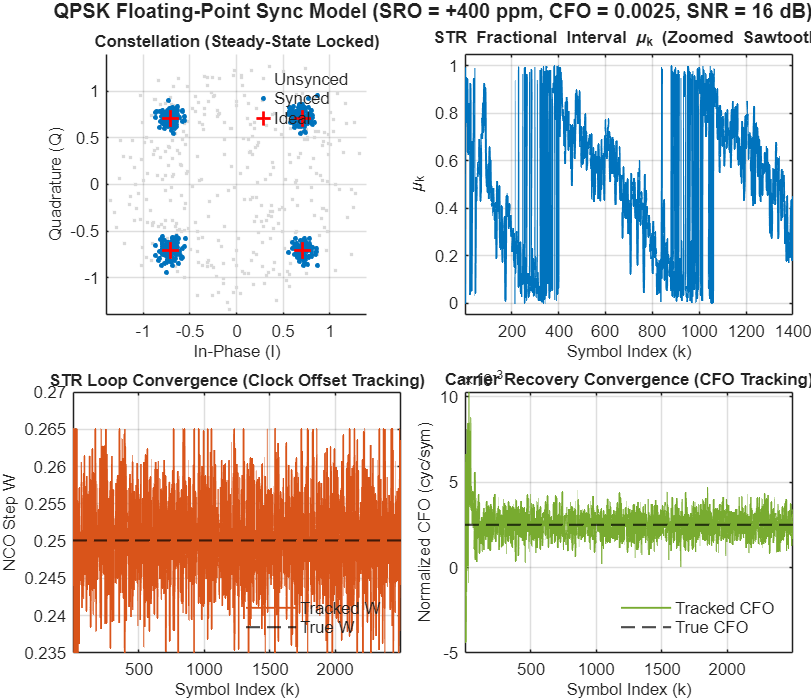


plot_clean_dashboard('QPSK', sps, sro_ppm, cfo_norm, snr_qpsk, rx_mf, mu_log, W_log, sym_cr, freq_log, const_qpsk);

## 7. Extending the Model to 16-QAM Mode

Switching the receiver from QPSK to **16-QAM** requires **zero changes** to the STR loop or the PI loop filter equations. Only two things change:

- **Unit-Energy 16-QAM Normalization:** The 16 points lie on the grid $\{-3, -1, +1, +3\}$ scaled by $1/\sqrt{10}$ so $E_s = 1$.

- **4-Level Slicer:** In the CR loop, `sign()` is replaced by a 4-level quantizer clamped to $[-3, +3]$ on both I and Q rails.

Because 16-QAM decision boundaries are tighter than QPSK, we evaluate this mode at $\mathrm{SNR} = 22$ dB.

snr_16qam = 22;
lvls = [-3, -1, 1, 3];
[I_g, Q_g] = meshgrid(lvls, lvls);
const_16qam = (I_g(:) + 1j*Q_g(:)) / sqrt(10);
tx_16qam    = const_16qam(randi(16, N_sym, 1));

% Channel & Matched Filter (reuses inline h_rrc and identical impairment profile)
tx_up16 = zeros(N_sym * sps, 1);
tx_up16(1:sps:end) = tx_16qam;
tx_bb16 = conv(tx_up16, h_rrc, 'same');

t_adc16   = t_nom * (1 + sro_ppm * 1e-6) + tau_init * sps;
t_adc16   = t_adc16(t_adc16 <= (numel(tx_bb16) - 1));
rx_sro16  = interp1(t_nom, tx_bb16, t_adc16, 'spline');
rx_cfo16  = rx_sro16 .* exp(1j * (2*pi*(cfo_norm/sps)*n_idx + phi_init));
noise_p16 = mean(abs(rx_cfo16).^2) / (10^(snr_16qam / 10));
rx_mf16   = conv(rx_cfo16 + sqrt(noise_p16/2)*(randn(size(rx_cfo16))+1j*randn(size(rx_cfo16))), h_rrc, 'same');

% Identical STR Loop
buf4 = zeros(4,1); eta = 0.75; W = W_nom; int_str = 0; y_prev = 0; y_mid_hold = 0;
sym_str16 = zeros(max_syms, 1); mu_log16 = zeros(max_syms, 1); W_log16 = zeros(max_syms, 1);
sym_cnt16 = 0;

for n = 1:numel(rx_mf16)
    buf4 = [buf4(2:4); rx_mf16(n)];
    eta_temp = eta - W;
    if (eta >= 0.5) && (eta_temp < 0.5)
        mu_m = (eta - 0.5) / W;
        v0 = buf4(2); v1 = -0.5*buf4(4)+1.5*buf4(3)-0.5*buf4(2)-0.5*buf4(1); v2 = 0.5*buf4(4)-0.5*buf4(3)-0.5*buf4(2)+0.5*buf4(1);
        y_mid_hold = (v2 * mu_m + v1) * mu_m + v0;
    end
    if eta_temp < 0
        sym_cnt16 = sym_cnt16 + 1;
        mu_k = eta / W; eta_next = eta_temp + 1.0;
        v0 = buf4(2); v1 = -0.5*buf4(4)+1.5*buf4(3)-0.5*buf4(2)-0.5*buf4(1); v2 = 0.5*buf4(4)-0.5*buf4(3)-0.5*buf4(2)+0.5*buf4(1);
        y_cur = (v2 * mu_k + v1) * mu_k + v0;
        e_ted = real(y_mid_hold)*(real(y_cur)-real(y_prev)) + imag(y_mid_hold)*(imag(y_cur)-imag(y_prev));
        int_str = int_str + Ki_str * e_ted;
        W = max(min(W_nom + Kp_str*e_ted + int_str, 0.265), 0.235);
        y_prev = y_cur;
        sym_str16(sym_cnt16) = y_cur; mu_log16(sym_cnt16) = mu_k; W_log16(sym_cnt16) = W;
    else
        eta_next = eta_temp;
    end
    eta = eta_next;
end
sym_str16 = sym_str16(1:sym_cnt16); mu_log16 = mu_log16(1:sym_cnt16); W_log16 = W_log16(1:sym_cnt16);

% CR Loop with 16-QAM 4-Level Slicer
phase_cur = 0.0; int_cr = 0.0;
sym_cr16  = zeros(sym_cnt16, 1); freq_log16 = zeros(sym_cnt16, 1);

for k = 1:sym_cnt16
    y_rot = sym_str16(k) * exp(-1j * phase_cur);

    % 16-QAM 4-level slicer: {-3, -1, +1, +3} / sqrt(10)
    re_s  = max(min(2 * round((real(y_rot)*sqrt(10) + 1) / 2) - 1, 3), -3);
    im_s  = max(min(2 * round((imag(y_rot)*sqrt(10) + 1) / 2) - 1, 3), -3);
    s_hat = (re_s + 1j*im_s) / sqrt(10);

    e_ped     = imag(y_rot * conj(s_hat));
    int_cr    = int_cr + Ki_cr * e_ped;
    freq_word = Kp_cr * e_ped + int_cr;
    phase_cur = mod(phase_cur + 2*pi*freq_word + pi, 2*pi) - pi;

    sym_cr16(k)   = y_rot;
    freq_log16(k) = freq_word;
end

% Compute 16-QAM Steady-State EVM & Plot Dashboard
steady_16 = sym_cr16(end-600 : end);
re_d = max(min(2 * round((real(steady_16)*sqrt(10) + 1) / 2) - 1, 3), -3);
im_d = max(min(2 * round((imag(steady_16)*sqrt(10) + 1) / 2) - 1, 3), -3);
dec_16 = (re_d + 1j*im_d) / sqrt(10);
evm_16qam = 100 * sqrt(mean(abs(steady_16 - dec_16).^2) / mean(abs(dec_16).^2));

fprintf('=== 16-QAM SUMMARY ===\n');

=== 16-QAM SUMMARY ===


fprintf('  True W   = %.6f | Mean Tracked W   = %.6f\n', W_nom*(1+sro_ppm*1e-6), mean(W_log16(end-500:end)));

  True W   = 0.250100 | Mean Tracked W   = 0.250440


fprintf('  True CFO = %.6f | Mean Tracked CFO = %.6f\n', cfo_norm, mean(freq_log16(end-500:end)));

  True CFO = 0.002500 | Mean Tracked CFO = 0.002492


fprintf('  Steady-State EVM = %.2f %%\n\n', evm_16qam);

  Steady-State EVM = 6.73 %



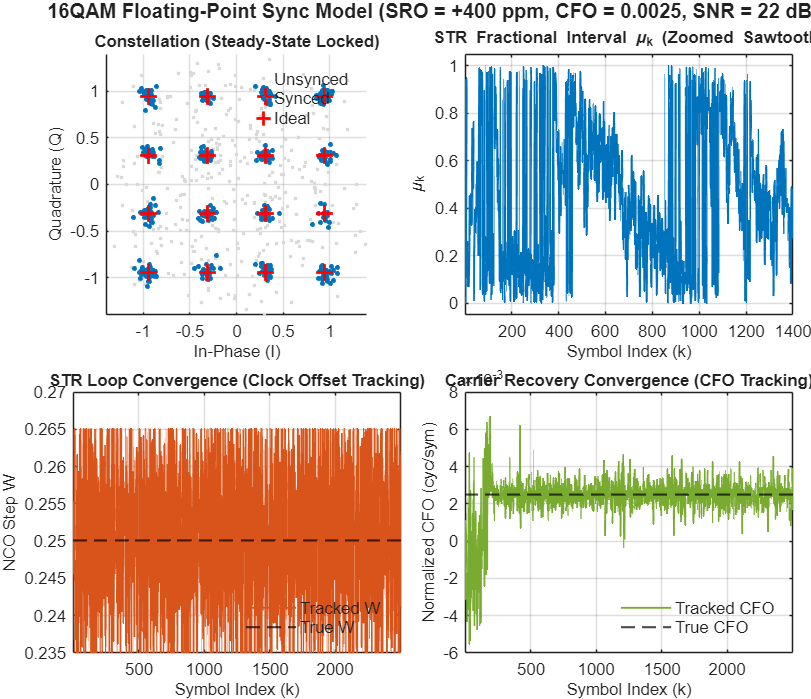


plot_clean_dashboard('16QAM', sps, sro_ppm, cfo_norm, snr_16qam, rx_mf16, mu_log16, W_log16, sym_cr16, freq_log16, const_16qam);

## Local Utility Function (PDF-Friendly Plotting)

function plot_clean_dashboard(mode, sps, sro_ppm, cfo_norm, snr_db, rx_mf, mu_log, W_log, sym_cr, freq_log, ideal_const)
    % Portrait-friendly figure size in inches so PDF export stays large and crisp
    fig = figure('Name', [mode ' Synchronization Golden Model'], ...
                 'Color', 'w', 'Units', 'inches', 'Position', [0 0 7.2 6.2]);

    % Compact/tight spacing removes wasted margins around subplots
    tl = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'tight');
    title(tl, sprintf('%s Floating-Point Sync Model (SRO = +%d ppm, CFO = %.4f, SNR = %d dB)', ...
          mode, sro_ppm, cfo_norm, snr_db), 'FontWeight', 'bold', 'FontSize', 12);

    % Panel 1: Steady-State Constellation
    nexttile;
    raw_sub = rx_mf(1 : sps : end);
    raw_vis = raw_sub(end-350 : end);
    lck_vis = sym_cr(end-450 : end);
    hold on; grid on; axis equal;
    plot(real(raw_vis), imag(raw_vis), '.', 'Color', [0.85 0.85 0.85], 'MarkerSize', 6);
    plot(real(lck_vis), imag(lck_vis), '.', 'Color', [0.00 0.45 0.74], 'MarkerSize', 9);
    plot(real(ideal_const), imag(ideal_const), 'r+', 'MarkerSize', 10, 'LineWidth', 1.6);
    xlim([-1.4 1.4]); ylim([-1.4 1.4]);
    xlabel('In-Phase (I)'); ylabel('Quadrature (Q)');
    title('Constellation (Steady-State Locked)');
    legend({'Unsynced', 'Synced', 'Ideal'}, 'Location', 'northeast', 'Box', 'off');

    % Panel 2: STR Fractional Interval mu_k (Zoomed Sawtooth)
    nexttile;
    win = min(1400, numel(mu_log));
    plot(1:win, mu_log(1:win), 'Color', [0.00 0.45 0.74], 'LineWidth', 1.2);
    grid on; ylim([-0.05 1.05]); xlim([1 win]);
    xlabel('Symbol Index (k)'); ylabel('\mu_k');
    title('STR Fractional Interval \mu_k (Zoomed Sawtooth)');

    % Panel 3: STR NCO Control Word W Convergence
    nexttile;
    W_true = (1/sps) * (1 + sro_ppm * 1e-6);
    plot(W_log, 'Color', [0.85 0.33 0.10], 'LineWidth', 1.1); hold on;
    yline(W_true, 'k--', 'LineWidth', 1.3);
    grid on; xlim([1 numel(W_log)]);
    xlabel('Symbol Index (k)'); ylabel('NCO Step W');
    title('STR Loop Convergence (Clock Offset Tracking)');
    legend({'Tracked W', 'True W'}, 'Location', 'southeast', 'Box', 'off');

    % Panel 4: Carrier Recovery Frequency Tracking
    nexttile;
    plot(freq_log, 'Color', [0.47 0.67 0.19], 'LineWidth', 1.1); hold on;
    yline(cfo_norm, 'k--', 'LineWidth', 1.3);
    grid on; xlim([1 numel(freq_log)]);
    xlabel('Symbol Index (k)'); ylabel('Normalized CFO (cyc/sym)');
    title('Carrier Recovery Convergence (CFO Tracking)');
    legend({'Tracked CFO', 'True CFO'}, 'Location', 'southeast', 'Box', 'off');

    % Boost all axis, tick, and label font sizes for readability in PDF
    set(findall(fig, '-property', 'FontSize'), 'FontSize', 10);
end